# SRS资源映射

SRS（Sounding Reference Signal）是一种关键的上行链路信号，用于无线资源管理、质量测量和调度，以确保5G网络的高性能和高效率运行。它允许基站了解终端设备的信道状况，从而更好地满足不同应用和服务的需求。

- 上行链路质量测量：SRS信道主要用于终端设备（如手机）向基站报告上行链路的质量。终端设备周期性地发送SRS信号，基站通过分析这些信号可以了解信道的状况，包括信号功率、多径衰落情况等。

- 频域位置：SRS信道在频域上占用一定的带宽，通常与用户数据信号不同。这有助于基站区分SRS信号和用户数据信号，并有效地进行资源分配和调度。

- 调度和资源分配：基站可以根据SRS信号的信息来决定如何最优地分配资源给不同的终端设备。这有助于提高网络的性能和效率。

- SRS配置：5G系统允许配置SRS的参数，如周期性发送的时间间隔、频率偏移等，以适应不同的网络和业务需求。

- 用于MIMO系统：多输入多输出（MIMO）技术在5G中得到广泛应用，SRS信道也可以用于MIMO系统中，帮助基站确定适当的波束形成和天线选择。

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 273;               % Size of carrier in RB

## 2 SRS资源配置

**时域**：时域符号数和时域重复

**频域**：

- freqDomainShift：SRS宽带资源的起始RB。

- freqDomainPosition：SRS子带循环移位。

- BHop >= BSRS：跳频不使能，SRS宽带等于BSRS对应的m_SRS，SRS子带等于BSRS对应的m_SRS。

- BHop <   BSRS：跳频使能，SRS宽带等于BHop对应的m_SRS，SRS子带等于BSRS对应的m_SRS。

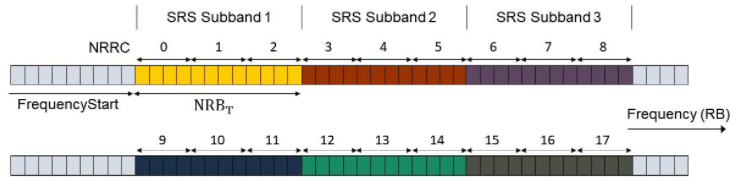

**梳分**：梳分数和梳分偏移

**码域**：CyclicShift

% SRS configuration
srs = nrSRSConfig;
srs.NumSRSPorts = 2;      % Number of SRS antenna ports (1/2/4)
srs.NumSRSSymbols = 1;    % Number of OFDM symbols (1/2/4)
srs.SymbolStart = 13;     % 0-based index of first OFDM symbol (8...13)
srs.KTC = 4;              % 梳分数 (2/4)
srs.KBarTC = 0;           % 梳分偏移 (0...KTC-1)
srs.CyclicShift = 0;      % 梳分循环移位 (KTC=2 0...7; KTC=4 0...11)
srs.FrequencyStart = 0;   % Frequency-domain offset (0...271)
srs.NRRC = 0;             % Additional circular frequency-domain offset (0...67)
srs.CSRS = 63;            % Bandwidth configuration C_SRS (0...63)
srs.BSRS = 1;             % Bandwidth configuration B_SRS (0...3)
srs.BHop = 0;             % Frequency hopping index (0...3)
srs.Repetition = 1;       % Repetition factor of OFDM symbols (Repetition ≤ NumSRSSymbols)
srs.SRSPeriod = 'on';   % 'on' (default) | 'off' | [TSRS Toffset]
srs.ResourceType = 'periodic';
srs.GroupSeqHopping = 'neither';
srs.NSRSID = 0;           % SRS scrambling identity
srs.SRSPositioning = false;

% 计算SRS子带带宽和数目
srs_band_config = srs.BandwidthConfigurationTable(srs.CSRS+1,:);
N_values = [srs_band_config.N_0, srs_band_config.N_1, srs_band_config.N_2, srs_band_config.N_3];
num_srs_subband = prod(N_values(1:srs.BSRS+1));
info = table([srs.NRB; srs.NRBPerTransmission;num_srs_subband],'RowNames', {'Freq-Hopping bandwidth (RB)','Instantaneous bandwidth (RB)','SRS subband num'},'VariableNames',"info");
disp(info)

                                    info
                                    ____

    Freq-Hopping bandwidth (RB)     272 
    Instantaneous bandwidth (RB)     16 
    SRS subband num                  17 



## 3 资源映射

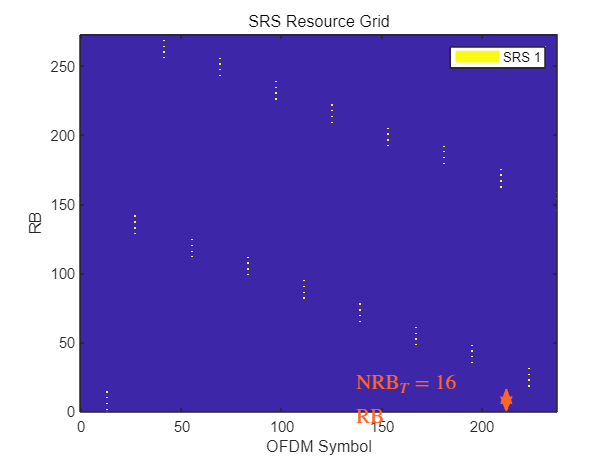

srsSym = nrSRS(carrier,srs);
srsInd = nrSRSIndices(carrier,srs);

carrierGrid = nrResourceGrid(carrier,srs.NumSRSPorts);
carrierGrid(srsInd) = srsSym;

slot_duration = num_srs_subband;
hSRSGrid(carrier,srs,slot_duration,true);
title('SRS Resource Grid');
hSRSAnnotations(carrier,srs);

## 4 附录

### （1）SRS资源信元

### **（2）SRS bandwidth configuration（38211 Table 6.4.1.4.3-1:）**

function [csrs,bsrs] = hSRSBandwidthConfiguration(srs, NRB)
% [CSRS,BSRS] = hBandwidthConfiguration(SRS, NRB) returns the SRS
% bandwidth configuration parameters CSRS and BSRS required to transmit an
% SRS in a bandwidth specified by NRB. The function calculates CSRS and
% BSRS considering the SRS properties FrequencyStart and NRRC, so the
% available bandwidth NRB is reduced by the frequency origin of the SRS.
% For frequency hopping cases, the value of BSRS returned is equal to that
% of the BSRS property in the input SRS configuration object.

    f0 = hSRSFrequencyOrigin(srs);
    NRB = NRB - f0;
    if NRB < 4
        error('The available bandwidth is not sufficient to allocate an SRS transmission. Increase the carrier bandwidth or configure the SRS in a lower frequency.' )    
    end
    
    % For frequency hopping configurations
    if srs.BHop >= srs.BSRS && nargout == 2 % No frequency hopping and BSRS is requested
        BSRS = 0:3;
    else
        BSRS = 0;
    end
    
    % Initialize gap between SRS frequency allocation and carrier bandwidth
    NRBGap = NRB; 
    
    % Find the appropriate CSRS for each BSRS that minimizes the gap only
    % in non-hopping cases. For freq. hopping, find the value of CSRS only.
    for b = BSRS
        % NRB allocated to the SRS for BSRS = b and all CSRS
        srsNRBb = srs.BandwidthConfigurationTable{:,2*(b+1)};
        mSRSbMax = max( srsNRBb( srsNRBb <= NRB ));
        
        % Calculate gap between SRS allocation and carrier bandwidth
        gap = NRB - mSRSbMax;
        if gap < NRBGap
            csrs = srs.BandwidthConfigurationTable{ srsNRBb == mSRSbMax ,1};
            bsrs = b;
            NRBGap = gap;
        end
    end
    csrs = csrs(1);
    
    if srs.BHop < bsrs
        bsrs = srs.BSRS;
    end
end

function out = hSRSNumberOfSubbandsOrHoppingPatterns(srs)
% N = hSRSNumberOfSubbandsOrHoppingPatterns(SRS) returns the number of
% unique SRS subbands or frequency-hopping patterns N configurable by the
% SRS property NRRC. An SRS subband is the frequency band allocated for SRS
% in a given OFDM symbol (See SRS property NRBPerTransmission). N is
% calculated using TS 38.211 Table 6.4.1.4.3-1 for the bandwidth
% configuration parameters CSRS, BSRS, and BHop specified in the SRS
% configuration object SRS.

    bwct = nrSRSConfig.BandwidthConfigurationTable{:,:};
    if srs.BHop < srs.BSRS % Number of unique frequency-hopping patterns
        b0 = srs.BHop+1;
    else % Number of unique SRS subbands
        b0 = 0;
    end
    out = prod(bwct(srs.CSRS+1,2*(b0:srs.BSRS)+3));
end

function [Grid,dispGrid] = hSRSGrid(carrier,srs,Duration,displayGrid,chplevels)
% [GRID,DISPGRID] = hSRSGrid(CARRIER,SRS,DURATION,DISPLAYGRID,CHPLEVELS)
% returns a multi-slot OFDM resource grid GRID containing a set of sounding
% reference signals in a carrier, as specified by the configuration objects
% CARRIER and SRS. This function also returns a scaled version of the grid
% used for display purposes. The optional input DURATION (Default 1)
% specifies the number of slots of the generated grid. The resource grid
% can be displayed using the optional input DISPLAYGRID (Default false).
% CHPLEVELS specifies the channel power levels for display purposes only
% and it must be of the same size as SRS.

    numSRS = length(srs);
    if nargin < 5
        chplevels = 1:-1/numSRS:1/numSRS;
        if nargin < 4
            displayGrid = false;
            if nargin < 3
                Duration = 1;
            end
        end
    end
    
    SymbolsPerSlot = carrier.SymbolsPerSlot;
    emptySlotGrid = nrResourceGrid(carrier,max([srs(:).NumSRSPorts])); % Initialize slot grid
    
    % Create the SRS symbols and indices and populate the grid with the SRS symbols
    Grid = repmat(emptySlotGrid,1,Duration);
    dispGrid = repmat(emptySlotGrid,1,Duration); % Frame-size grid for display
    for ns = 0:Duration-1
        slotGrid = emptySlotGrid;
        dispSlotGrid = emptySlotGrid; % Slot-size grid for display
        for ich = 1:numSRS
            srsIndices = nrSRSIndices(carrier,srs(ich));
            srsSymbols = nrSRS(carrier,srs(ich));
            slotGrid(srsIndices) = srsSymbols;
            dispSlotGrid(srsIndices) = chplevels(ich)*srsSymbols; % Scale the SRS for display only
        end
        OFDMSymIdx = ns*SymbolsPerSlot + (1:SymbolsPerSlot);
        Grid(:,OFDMSymIdx,:) = slotGrid;
        dispGrid(:,OFDMSymIdx,:) = dispSlotGrid;
        carrier.NSlot = carrier.NSlot+1;
    end
    
    if displayGrid
        plotGrid(dispGrid(:,:,1),chplevels,"SRS " + (1:numSRS)'); 
    end
end
    
function varargout = plotGrid(Grid,chplevels,leg)
% plotGrid(GRID, CHPLEVEL,LEG) displays a resource grid GRID containing
% channels or signals at different power levels CHPLEVEL and create a
% legend for these using a cell array of character vector LEG

    if nargin < 3
        leg = {'SRS'};
        if nargin < 2
            chplevels = 1;
        end
    end
    
    cmap = colormap(gcf);
    chpscale = length(cmap); % Scaling factor
    
    h = figure;
    image(0:size(Grid,2)-1,(0:size(Grid,1)-1)/12,chpscale*abs(Grid(:,:,1))); % Multiplied with scaling factor for better visualization
    axis xy;
    
    title('Carrier Grid Containing SRS')
    xlabel('OFDM Symbol'); ylabel('RB');
    
    clevels = chpscale*chplevels(:);
    N = length(clevels);
    L = line(ones(N),ones(N),'LineWidth',8); % Generate lines
    
    % Index the color map and associate the selected colors with the lines
    set(L,{'color'},mat2cell(cmap( min(1+fix(clevels),length(cmap) ),:),ones(1,N),3)); % Set the colors according to cmap
    
    % Create legend
    legend(leg(:));
    
    if nargout > 0 
        varargout = {h};
    end
end

function hSRSAnnotations(carrier,srs)
% hSRSAnnotations(carrier,srs) adds annotation to the current figure
% indicating the frequency origin of the SRS and the number of RB used per
% OFDM symbol for the configuration objects CARRIER and SRS.

    % Calculate the frequency origin of the first SRS symbol
    f0 = hSRSFrequencyOrigin(srs);
    
    hold on;
    hfig = gcf;
    set(hfig,'Units','Normalized');
    Sym0 = srs.SymbolStart-0.5;
    if isnumeric(srs.SRSPeriod)
        Sym0 = srs.SRSPeriod(2)*carrier.SymbolsPerSlot + srs.SymbolStart-0.5;
    end
    
    IP = get(gca,'Position');
    
    % Y-coordinate in the current axes of the SRS freq position f0
    Yf0 = f0/carrier.NSizeGrid*IP(4)+IP(2);
    Xc = Sym0/((carrier.NSlot+1)*carrier.SymbolsPerSlot)*IP(3)+IP(1);
    
    % Add annotation to the figure including f0 in RB
    if f0/carrier.NSizeGrid > 0.08 % Only plot f0 when there is enough space in the y-axis
        % Create doublearrow for F0
        YMin = IP(2);
        annotation(hfig,'doublearrow',Xc*[1 1], [YMin Yf0],...
            'Color',[1 0.4 0.15]);
        
        % Text for F0
        str = sprintf('$$F_0 = %d $$ RB', f0);
        Ystr = f0/carrier.NSizeGrid/2;
        text(gca,(Xc-IP(1))/IP(3)-0.25, Ystr,str,...
            'Color',[1 0.4 0.15],'FontSize',14, ...
            'Units','Normalized','Interpreter','latex');
    end
    
    % Create doublearrow from f0 and spanning the SRS bandwidth
    Yf1 = Yf0 + srs.NRBPerTransmission/carrier.NSizeGrid*IP(4);
    annotation(hfig,'doublearrow',Xc*[1 1], [Yf0 Yf1],...
        'Color',[1 0.4 0.15]);
    
    % Text for NRBt
    str = sprintf('$$\\textrm{NRB}_T = %d $$ RB', srs.NRBPerTransmission);
    Ystr = (f0 + 0.5*srs.NRBPerTransmission)/carrier.NSizeGrid;
    text(gca,(Xc-IP(1))/IP(3)-0.32, Ystr ,str,...
        'Color',[1 0.4 0.15],'FontSize',14, ...
        'Units','Normalized','Interpreter','latex');
end

function f0 = hSRSFrequencyOrigin(srs)
% Calculate the frequency origin of the first SRS symbol in a slot

    NSBTable = hSRSNumberOfSubbandsOrHoppingPatterns(srs);
    NRBt = srs.NRBPerTransmission;
    
    % Origin of the SRS in frequency in RB
    f0 = srs.FrequencyStart + NRBt*mod(floor(4*srs.NRRC/NRBt),NSBTable);
end

function [NRRC,NRB] = hNRRCSet(srs)
% Calculate the values of NRRC that generate a unique set of orthogonal SRS in frequency
    if srs.BHop < srs.BSRS % Frequency-hopping cases
        NRB = srs(1).NRB;  % Hopping bandwidth
    else 
        NRB = nrSRSConfig.BandwidthConfigurationTable{srs(1).CSRS+1,2}; 
    end
    
    % Number of frequency-hopping patterns or SRS subbands depending on the values of BSRS and BHop
    N = hSRSNumberOfSubbandsOrHoppingPatterns(srs);
    
    NRRC = NRB/4*(0:N-1)/N; 
end